## Task 1

In Task I, you are expected to generate eye diagrams for baseband binary phase shift keying (BPSK) signaling with different pulse shaping filters

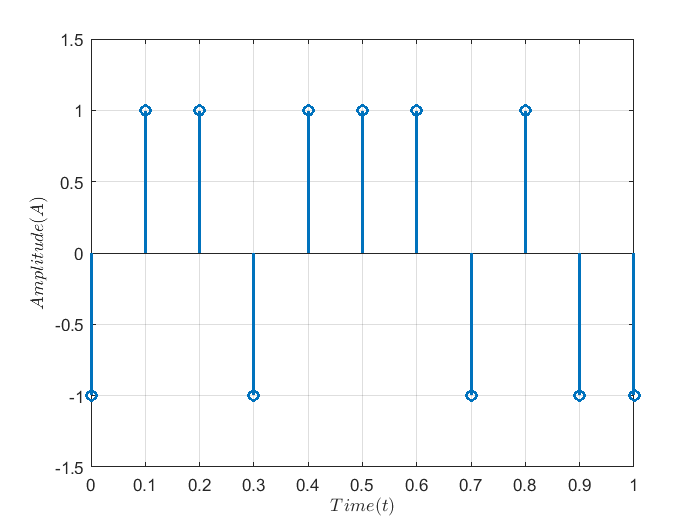

br = 10;            % bit rate of the gnerator 10 bits/second
Tb = 1/br;          % bit duration
A = 1;              % amplitude of the impulses
time_resolution = 100;  % number of data points between two impulses
delta_t = Tb/100;       % smallest unit of time
t_lim = 1;     % limit for the visualization in seconds from the beginning
time_duration = L*Tb;           % time to emmit all the bits in seconds
L = 1000;                       % length of the binary sequence
bin_seq = randi([0 1], 1, L);   % random binary sequence
t_com = 0:delta_t:time_duration;% common time vector

% Mapping binary data into impluses
imp_train1  = zeros(1,L); % impulse train representing BPSK symbols
for index = 1:L
    if bin_seq(index) == 1
        imp_train1(index) = +A;
    else
        imp_train1(index) = -A;
    end
end

t_impulse = 0:Tb:time_duration -Tb;
stem(t_impulse,imp_train1, 'LineWidth',2); grid on;
axis([0 t_lim -(3*A/2) (3*A/2)]);
ylabel("$ Amplitude(A)$",'Interpreter','latex');
xlabel("$ Time(t)$",'Interpreter','latex');

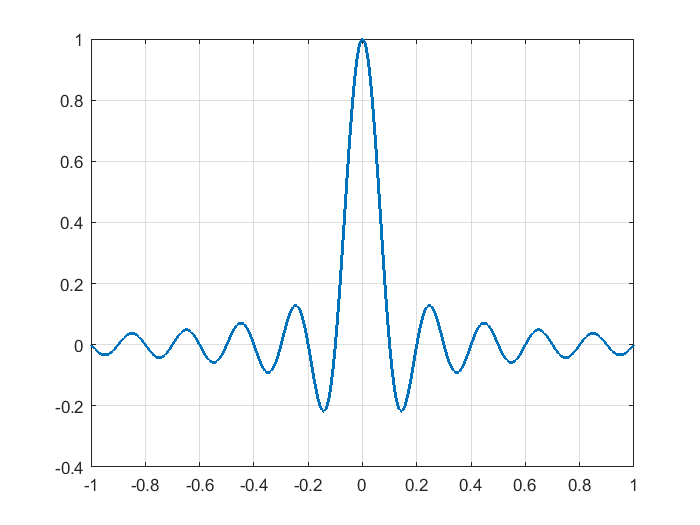

% generating the sinc filter
t_sinc = -t_lim: delta_t: t_lim;
sinc_pulse = sinc(t_sinc/Tb);
plot(t_sinc, sinc_pulse, 'LineWidth',2); grid on;

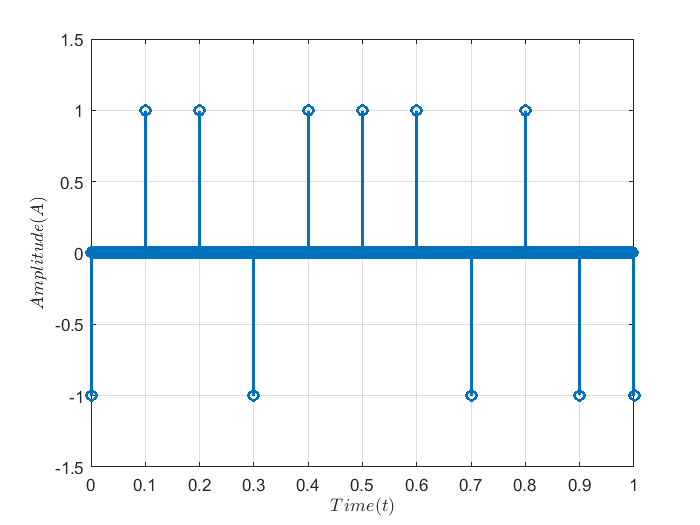

% for the convolution we need to take impulse train 
% and the sinc filter to a common time scale.
imp_train2 = zeros(1, length(t_com));
for index = 0:L-1
    imp_train2(index*time_resolution +1) = imp_train1(index +1);
end
stem(t_com,imp_train2, 'LineWidth',2); grid on;
axis([0 t_lim -(3*A/2) (3*A/2)]);
ylabel("$ Amplitude(A)$",'Interpreter','latex');
xlabel("$ Time(t)$",'Interpreter','latex');

% convolution of impulse train and the sinc filter
tx_signal = conv(imp_train2, sinc_pulse, 'same');
length(tx_signal)

ans = 100001

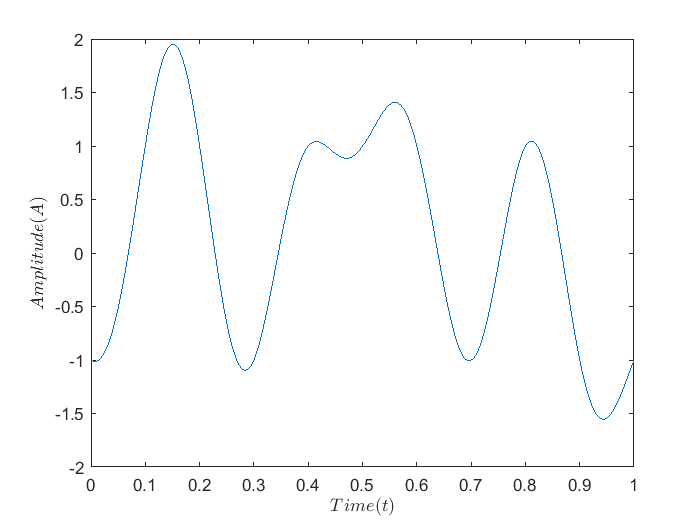

plot(t_com, tx_signal);
xlim([0 t_lim]);
ylabel("$ Amplitude(A)$",'Interpreter','latex');
xlabel("$ Time(t)$",'Interpreter','latex');